format long e

Question - 1

1 (a) 

n=5;
W = Wilkinson(n)

W =      1     0     0     0     1
    -1     1     0     0     1
    -1    -1     1     0     1
    -1    -1    -1     1     1
    -1    -1    -1    -1     1


1(b)

n=2;
H = Hamiltonian(n)

H =      5.376671395461000e-01    -2.258846861003648e+00     6.375304797179616e-01    -1.741280318610957e+00
     1.833885014595086e+00     8.621733203681206e-01    -1.741280318610957e+00     6.852489330772998e-01
     7.156793879451521e+00     1.419550089728356e+00    -5.376671395461000e-01    -1.833885014595086e+00
     1.419550089728356e+00     6.069846932663709e+00     2.258846861003648e+00    -8.621733203681206e-01


Question - 2

A = rand(8)

A =      9.571669482429456e-01     6.557406991565868e-01     6.554778901775566e-01     6.948286229758170e-01     1.868726045543786e-01     6.550980039738407e-01     7.512670593056529e-01     1.492940055590575e-01
     4.853756487228412e-01     3.571167857418955e-02     1.711866878115618e-01     3.170994800608605e-01     4.897643957882311e-01     1.626117351946306e-01     2.550951154592691e-01     2.575082541237365e-01
     8.002804688888001e-01     8.491293058687771e-01     7.060460880196088e-01     9.502220488383549e-01     4.455862007108995e-01     1.189976815583766e-01     5.059570516651424e-01     8.407172559836625e-01
     1.418863386272153e-01     9.339932477575505e-01     3.183284637742068e-02     3.444608050290876e-02     6.463130101112646e-01     4.983640519821430e-01     6.990767226566860e-01     2.542821789715310e-01
     4.217612826262750e-01     6.787351548577735e-01     2.769229849608900e-01     4.387443596563982e-01     7.093648308580726e-01     9.597439585160811e-01    

% maximum values in each column
max(A)

ans =      9.594924263929030e-01     9.339932477575505e-01     8.234578283272926e-01     9.502220488383549e-01     7.546866819823609e-01     9.597439585160811e-01     9.592914252054443e-01     9.292636231872278e-01


% maximum values in each row
max(A, [], 2)

ans =      9.571669482429456e-01
     4.897643957882311e-01
     9.502220488383549e-01
     9.339932477575505e-01
     9.597439585160811e-01
     9.592914252054443e-01
     9.292636231872278e-01
     9.594924263929030e-01



% Max value of overall matrix
max(max(A))

ans =      9.597439585160811e-01



% indices of elements larger than 0.25
[row, col] = find(A>0.25);
cat(2, row, col)

ans =      1     1
     2     1
     3     1
     5     1
     6     1
     7     1
     8     1
     1     2
     3     2
     4     2


Question - 3

A = magic(4)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


col_sum = sum(A)

col_sum =     34    34    34    34


row_sum = sum(A,2)

row_sum =     34
    34
    34
    34


diag_sum = sum(diag(A))

diag_sum =     34


A_flipped = flipud(A)

A_flipped =      4    14    15     1
     9     7     6    12
     5    11    10     8
    16     2     3    13


anti_diag_sum = sum(diag(A_flipped))

anti_diag_sum =     34


We can observe that all the values are same here which confirms that the magic() works fine.

Question - 4

4 (a) and (b)

N = [3,4,5];

for n = N
    fprintf('For n = %d\n', n);
    A = magic(n)
    
    s1 = sum(A)
    s2 = sum(A')'
    s3 = sum(diag(A))
    s4 = sum(diag(flipud(A)))
    r = rank(A)
    
    fprintf('After Applying commands of part (b)\n');
    p = randperm(n); q = randperm(n);
    A = A(p,q)
    
    s1 = sum(A)
    s2 = sum(A')'
    s3 = sum(diag(A))
    s4 = sum(diag(flipud(A)))
    r = rank(A)
end

For n = 3


A =      8     1     6
     3     5     7
     4     9     2


s1 =     15    15    15


s2 =     15
    15
    15


s3 =     15


s4 =     15


r =      3


After Applying commands of part (b)


A =      1     8     6
     5     3     7
     9     4     2


s1 =     15    15    15


s2 =     15
    15
    15


s3 =      6


s4 =     18


r =      3


For n = 4


A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


s1 =     34    34    34    34


s2 =     34
    34
    34
    34


s3 =     34


s4 =     34


r =      3


After Applying commands of part (b)


A =     15     1    14     4
    10     8    11     5
     3    13     2    16
     6    12     7     9


s1 =     34    34    34    34


s2 =     34
    34
    34
    34


s3 =     34


s4 =     34


r =      3


For n = 5


A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


s1 =     65    65    65    65    65


s2 =     65
    65
    65
    65
    65


s3 =     65


s4 =     65


r =      5


After Applying commands of part (b)


A =     14    23    16     7     5
     8    17    15     1    24
    20     4    22    13     6
    21    10     3    19    12
     2    11     9    25    18


s1 =     65    65    65    65    65


s2 =     65
    65
    65
    65
    65


s3 =     90


s4 =     40


r =      5


sum(A) prints sum of columns

sum(A')' prints sum of rows

sum(diag(A)) prints sum of diagonal elements of A

sum(diag(flipud(A))) prints sum of anti-diagonal elements of A

rank(A) prints rank of A

We observe that the commands in (b) part change the diagonal and anti-diagonal sum but the row, column sum and rank remains the same. (since it is random, sometimes the diagonal and anti-diagonal sum also turns out to be same)

4 (c)

A = magic(4)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


null(A)

ans =     -2.236067977499790e-01
    -6.708203932499368e-01
     6.708203932499369e-01
     2.236067977499789e-01


null(A, 'r')

ans =     -1
    -3
     3
     1


rref(A)

ans =      1     0     0     1
     0     1     0     3
     0     0     1    -3
     0     0     0     0


Question - 5

n = 3;
A = rand(n)

A =      1.621823081932428e-01     5.285331355062127e-01     2.629712845401443e-01
     7.942845406839070e-01     1.656487294997809e-01     6.540790984767823e-01
     3.112150420448049e-01     6.019819414016365e-01     6.892145031400078e-01



A^(-1)

ans =      2.433021444148833e+00     1.792449354975719e+00    -2.629396834212016e+00
     2.992566976247443e+00    -2.605344589292995e-01    -8.945677071341992e-01
    -3.712435152649106e+00    -5.818220019409659e-01     3.419576112560212e+00



A.^(-1)

ans =      6.165900653038459e+00     1.892028962464635e+00     3.802696563423994e+00
     1.258994665990811e+00     6.036870931758776e+00     1.528867077894398e+00
     3.213212296647385e+00     1.661179399620577e+00     1.450927099537340e+00



1./A

ans =      6.165900653038459e+00     1.892028962464635e+00     3.802696563423994e+00
     1.258994665990811e+00     6.036870931758776e+00     1.528867077894398e+00
     3.213212296647385e+00     1.661179399620577e+00     1.450927099537340e+00


This shows that (a) is false and (b) is true.

Question - 6

n = 4;
p = randn(1,n)

p =      1.711887782981555e+00    -1.941235357582654e-01    -2.138355269439939e+00    -8.395887473366136e-01



(length(p)-1:-1:0) .* p

ans =      5.135663348944664e+00    -3.882470715165308e-01    -2.138355269439939e+00                         0


Question - 7

7 (a)

arr1 = -2 * ones(1,16);
arr2 = ones(1,15);
arr3 = ones(1,1);

D = diag(arr1);
D = D + diag(arr2, 1) + diag(arr2, -1);
D = D + diag(arr3, 15) + diag(arr3, -15)

D =     -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0


7 (b)

arr = zeros(1,16);
arr(1) = -2; arr(2) = 1; arr(16) = 1;
D = toeplitz(arr)

D =     -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0


7 (c)

arr = [1,2,3,4,5,6,7,8];
D = triu(toeplitz(arr))

D =      1     2     3     4     5     6     7     8
     0     1     2     3     4     5     6     7
     0     0     1     2     3     4     5     6
     0     0     0     1     2     3     4     5
     0     0     0     0     1     2     3     4
     0     0     0     0     0     1     2     3
     0     0     0     0     0     0     1     2
     0     0     0     0     0     0     0     1


format rat
arr = 1 ./ arr;
D = toeplitz(arr)

D =        1              1/2            1/3            1/4            1/5            1/6            1/7            1/8     
       1/2            1              1/2            1/3            1/4            1/5            1/6            1/7     
       1/3            1/2            1              1/2            1/3            1/4            1/5            1/6     
       1/4            1/3            1/2            1              1/2            1/3            1/4            1/5     
       1/5            1/4            1/3            1/2            1              1/2            1/3            1/4     
       1/6            1/5            1/4            1/3            1/2            1              1/2            1/3     
       1/7            1/6            1/5            1/4            1/3            1/2            1              1/2     
       1/8            1/7            1/6            1/5            1/4            1/3            1/2            1       


Question - 8

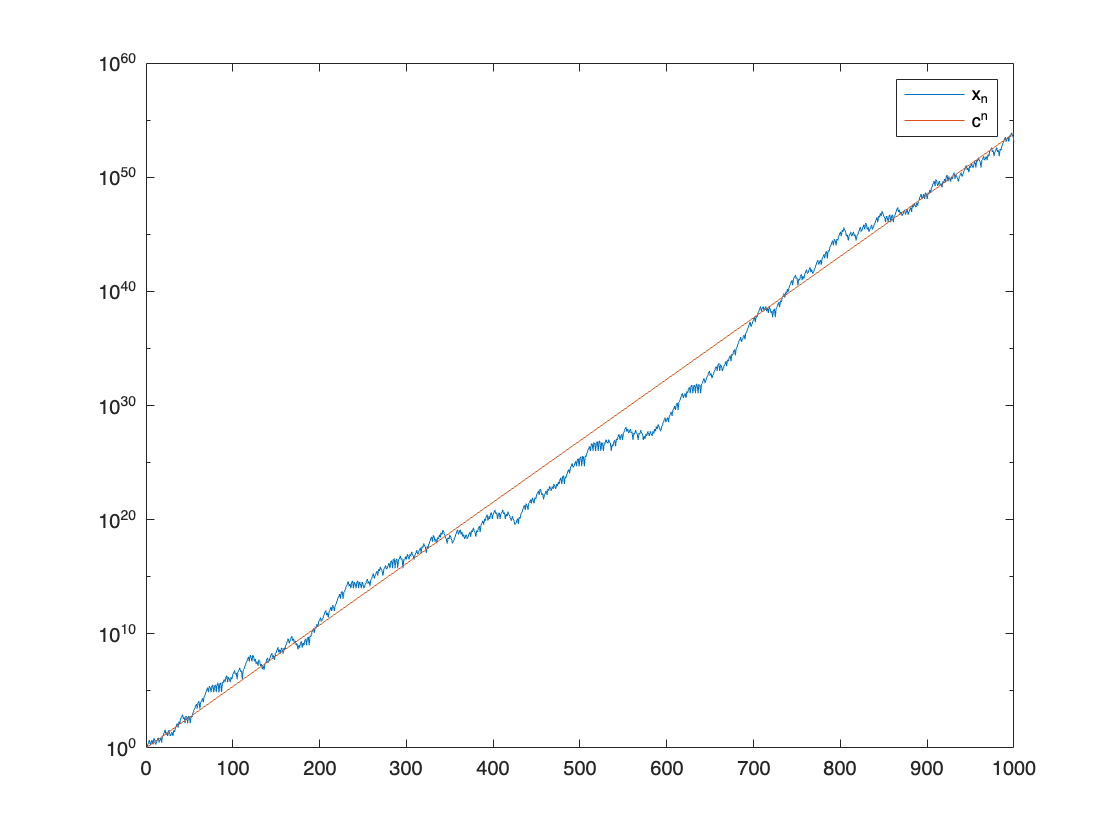

rand('state', 1000);
x = [1, 2];
for n=2:999, x(n+1) = x(n)+sign( rand-0.5)*x(n-1); end

figure;
semilogy (1:1000, abs(x))
c =1.13198824;
hold on
semilogy(1:1000, c.^[1:1000])
legend('x_n', 'c^n');
hold off;

Question - 9

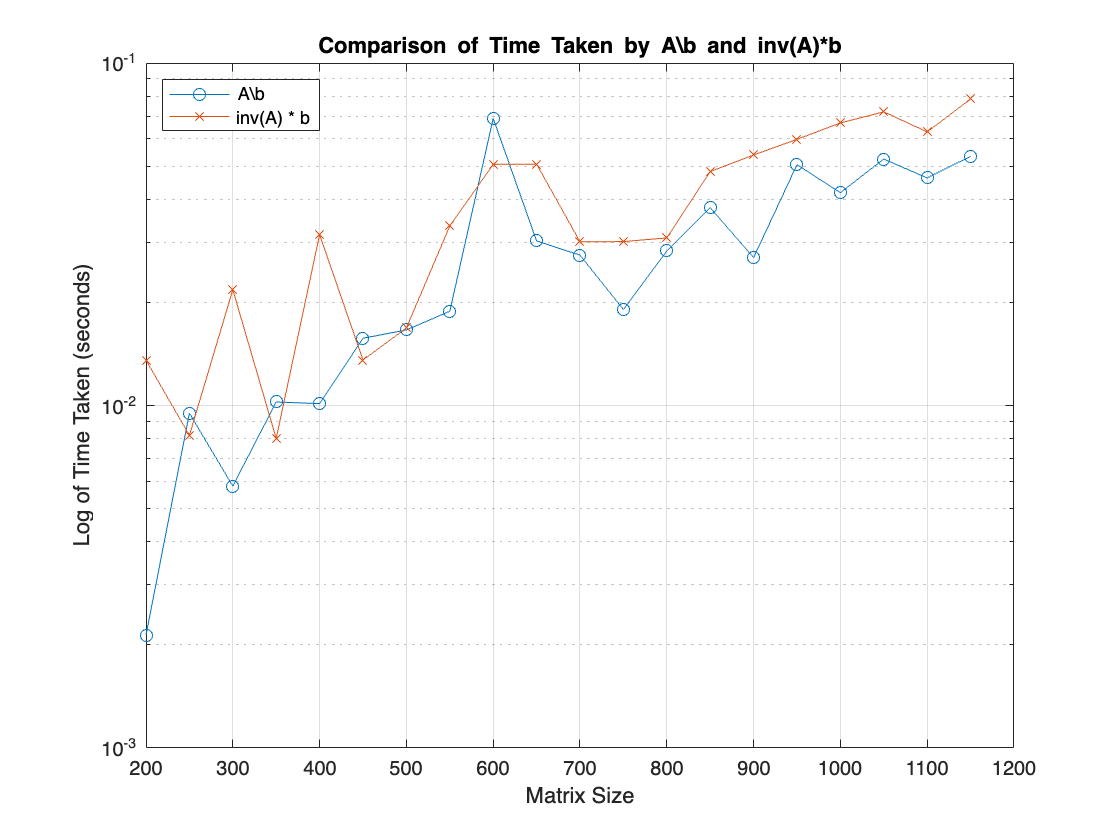

sizes = 200:50:1150;
num_matrices = length(sizes);

time_backslash = zeros(1, num_matrices);
time_inv = zeros(1, num_matrices);

for i = 1:num_matrices
    n = sizes(i);

    A = rand(n);
    b = rand(n, 1);

    tic;
    x_backslash = A\b;
    time_backslash(i) = toc;
    
    tic;
    x_inv = inv(A) * b;
    time_inv(i) = toc;
end

% Plot the results using semilogy to plot log of the time taken
figure;
semilogy(sizes, time_backslash, '-o', 'DisplayName', 'A\\b');
hold on;
semilogy(sizes, time_inv, '-x', 'DisplayName', 'inv(A) * b');
hold off;

title('Comparison of Time Taken by A\\b and inv(A)*b');
xlabel('Matrix Size');
ylabel('Log of Time Taken (seconds)');

legend('Location', 'northwest');
grid on;

Functions

function W = Wilkinson(n)
   W = eye(n);
   W = W - tril(ones(n), -1);
   W(:, end) = ones(n,1);
end

function H = Hamiltonian(n)
   H_11 = randn(n);
   H_22 = -H_11';
   
   H_12 = randn(n);
   H_12 = H_12 + H_12';
   
   H_21 = randn(n);
   H_21 = H_21 + H_21';
   
   H = cat(1, cat(2, H_11, H_12), cat(2, H_21, H_22));
end